# The Checkerboard Problem

http://www.mathworks.com/matlabcentral/cody/problems/4-make-a-checkerboard-matrix/solutions?sort=&term=status%3ACorrect

## Pour 1s and 0s into a grid

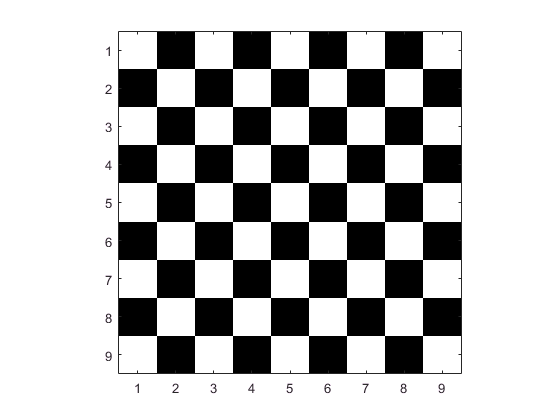

n = 9;

% This method fails for even numbers
elements = rem(1:n^2,2);
cb = reshape(elements,n,n);

imagesc(cb)
colormap(gray)
axis square

## Using meshgrid

n = 4;

[x,y] = meshgrid(1:n);
cb = 1-rem(x+y,2);

cb =      1     0     1     0
     0     1     0     1
     1     0     1     0
     0     1     0     1


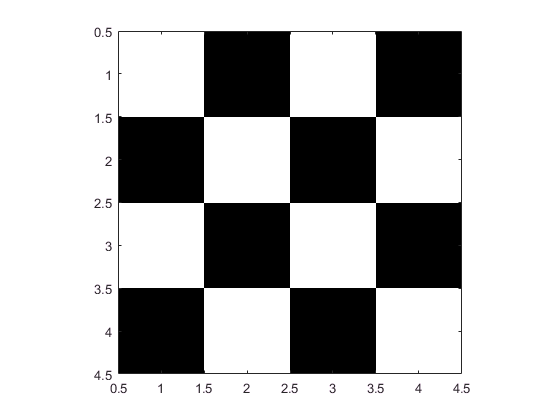


imagesc(cb)
colormap(gray)
axis square

## Every other element

n = 4;
cb = zeros(n);
cb(1:2:n,1:2:n) = 1;
cb(2:2:n,2:2:n) = 1;

imagesc(cb)
colormap(gray)
axis square

## Using spiral

n = 5;
cb = rem(spiral(n),2)

cb =      1     0     1     0     1
     0     1     0     1     0
     1     0     1     0     1
     0     1     0     1     0
     1     0     1     0     1


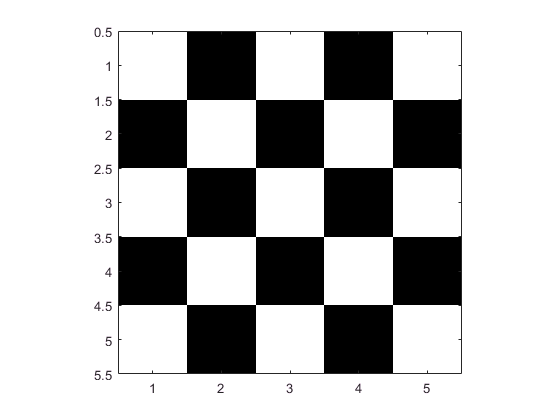


imagesc(cb)
colormap(gray)
axis square

## Using meshgrid

n = 4;

[x,y] = meshgrid(1:n);
cb = 1-rem(x+y,2)

cb =      1     0     1     0
     0     1     0     1
     1     0     1     0
     0     1     0     1



imagesc(cb)
colormap(gray)
axis square